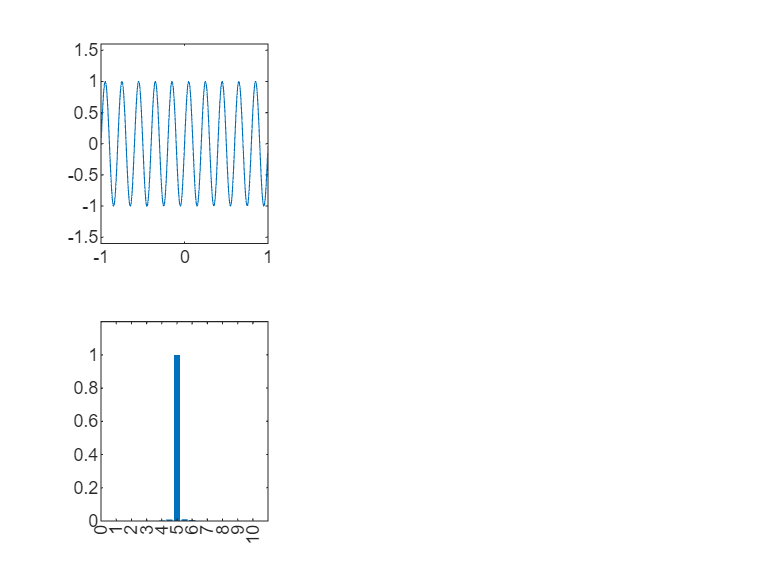

srate = 500;
time=-1:1/srate:1;

% create three sine waves
s1 = sin(2*pi*5*time);
s2 = 0.5*sin(2*pi*7*time);
s3 = s1+s2;

% plot the sine waves
figure
subplot(2,3,1)

% plot sine waves, using the eval command (evaluate the string)
plot(time,s1);
set(gca,'ylim',[-1.6 1.6],'ytick',-1.5:.5:1.5)

% plot power
subplot(2,3,1+3)
f  = fft(s1)/length(time);
hz = linspace(0,srate/2,floor(length(time)/2)+1);
bar(hz,abs(f(1:length(hz))*2))
set(gca,'xlim',[0 11],'xtick',0:10,'ylim',[0 1.2])

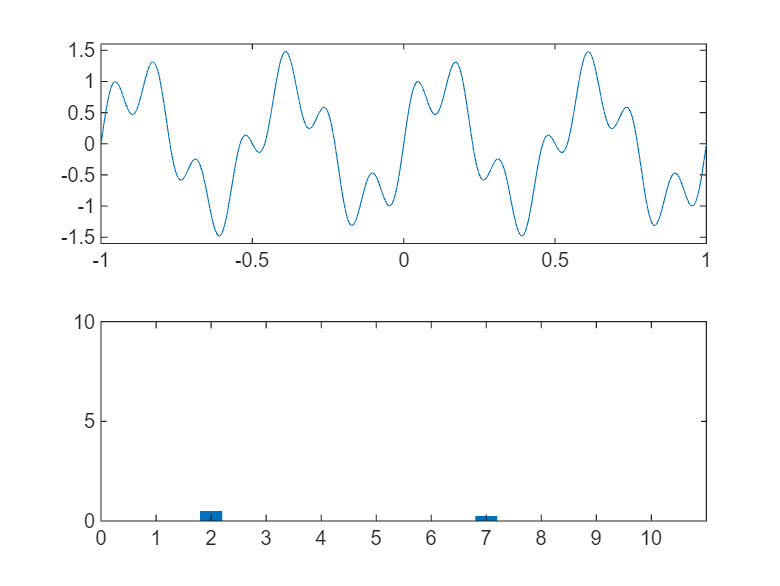

srate = 500;
time = -1:1/srate:1;

s1 = sin(2*pi*2*time) + 0.5*sin(2*pi*7*time);

figure;
subplot(211);
plot(time, s1)
set(gca,'ylim',[-1.6 1.6],'ytick',-1.5:.5:1.5);

subplot(212)
f = fft(s1)/length(time);
hz = linspace(0,srate/2,floor(length(time)/2)+1);

bar(hz, abs(f(1:length(hz))))
set(gca,'xlim',[0 11],'xtick',0:10,'ylim',[0 10])

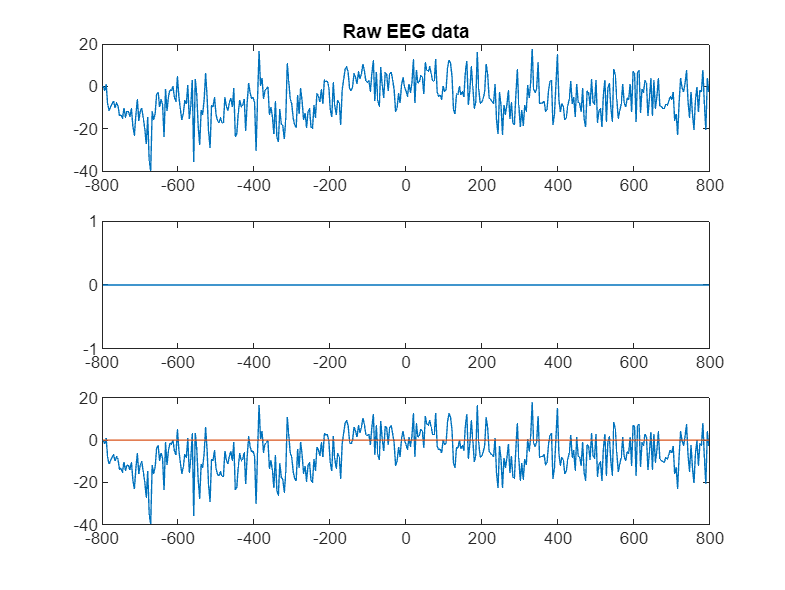

load("sampleEEGdata.mat")

range = find(EEG.times >= -800,1):find(EEG.times <= 800, 1, 'last');
signal = EEG.data(3,range,67);

s = 5/(2*pi*30);
g_kernel = exp((-range.^2)/(2*s^2))/30;

figure;
subplot(311)
plot(EEG.times(range), signal)
title("Raw EEG data")

subplot(312)
plot(EEG.times(range),g_kernel)
xlim = -800:800; 

subplot(313)
plot(EEG.times(range),signal)
hold on
conv_result = conv(signal, g_kernel, 'same');
plot(EEG.times(range),conv_result)
hold off

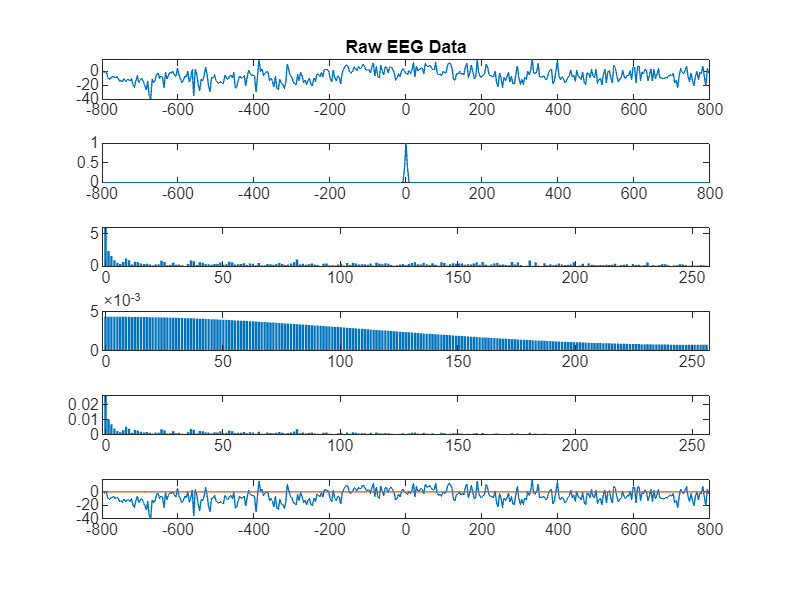

figure;

subplot(611)
plot(EEG.times(range), signal)
title("Raw EEG Data")

subplot(612)
plot(EEG.times(range),g_kernel)
xlim = -800:800; 

subplot(613)
sF = fft(signal)/length(range);
hz = linspace(0, 256,floor(length(range)/2) + 1);
bar(hz, abs(sF(1:length(hz))))

subplot(614)
kF = fft(g_kernel)/length(range);
hz = linspace(0, 256,floor(length(range)/2) + 1);
bar(hz, abs(kF(1:length(hz))))

subplot(615)
convF = sF.*kF;
hz = linspace(0, 256,floor(length(range)/2) + 1);
bar(hz, abs(convF(1:length(hz))))

subplot(616)
conv_result = ifft(convF)*length(range);
plot(EEG.times(range), signal)
hold on
plot(EEG.times(range), conv_result)